% Clustering using k-means
clc;clear;close all;

% input arguement
% pathTr = [pwd,'/USPS_train.txt'];
pathTr = '../DataSets/USPS_train.txt';
ITER = 70;

dTr = load(pathTr);
[X,y] = deal(dTr(:,1:end-1),dTr(:,end));
[dLen,Dim] = size(X);	% length and dimension of data
nCls = numel(unique(y));
% pre-processing
% Xbar = X-mean(X);
Xbar = (X-mean(X))./std(X);

## PCA

Sigma = Xbar*Xbar'/dLen;
[V,D] = eig(Sigma);
save('sigma.mat','V','D');

## Clustering

load('sigma.mat');
acc = zeros(Dim-1,ITER);

% Assign random class to data
yRand = randi([0 9],dLen,1);

% testing for different # of principal components
for p = 1:Dim
    if p==Dim
        xPCA = Xbar;
    else
        xPCA = V(:,end-p+1:end);
    end
    
    yEst = yRand;
    meanCls = zeros(nCls,size(xPCA,2));
    for iter = 1:ITER
        % Calculate mean of each class
        for i = 1:nCls
            meanCls(i,:) = mean(xPCA(yEst==(i-1),:));
        end
        
        % Assign new class to data
        for n = 1:dLen
            dEucl = sqrt(sum((xPCA(n,:)-meanCls).^2,2));	% distance from means
            [~,minD] = min(dEucl);  % minimum distance
            yEst(n) = minD-1;   % new class
        end
        clsErr = 0;
        % calculate accuracy
        for i = 1:nCls
            % find dominant class
            yCls = y(yEst==(i-1));
            [~,domCls] = max(hist(yCls,(0:9)));	%#ok
            domCls = domCls-1;
            % count classification error among all classes
            clsErr = clsErr+sum(yCls-domCls~=0);
        end
        acc(p,iter) = 1-clsErr/dLen;
    end
end

## Plot

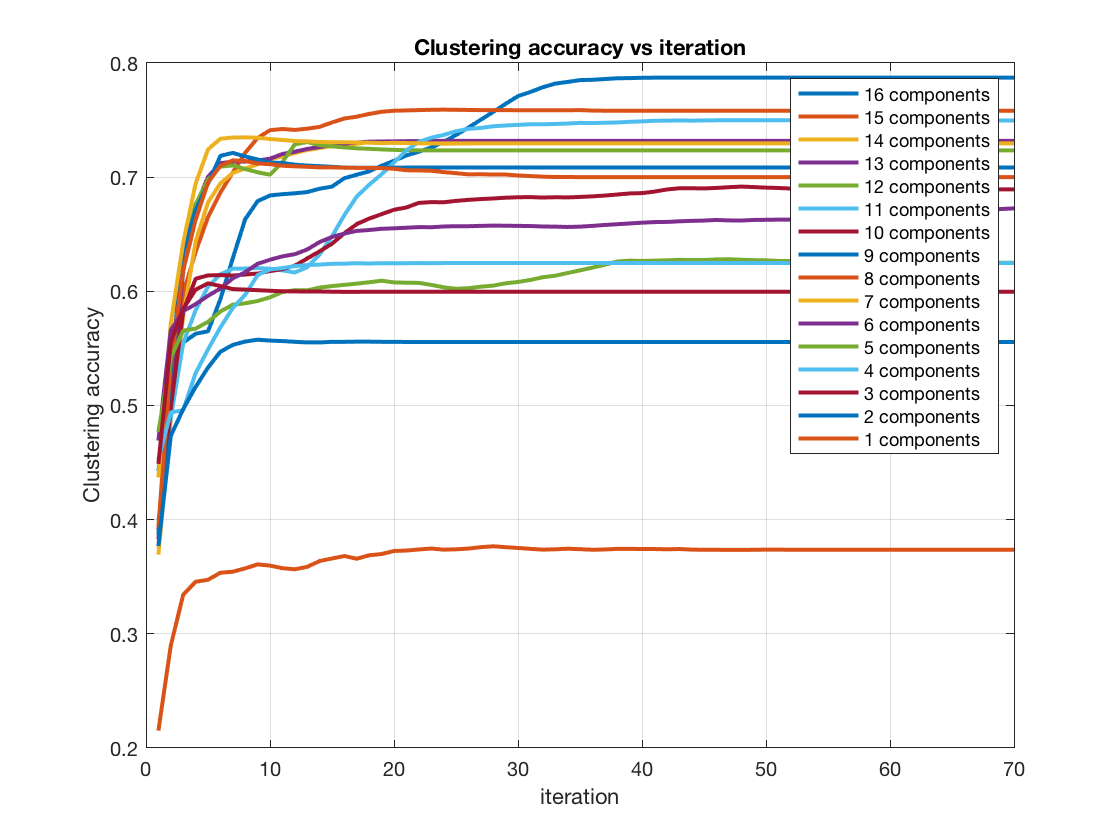

legendStr = cell(Dim,1);
figure
for p = Dim:-1:1
    plot(1:ITER,acc(p,:),'LineWidth',2);hold on;
    legendStr{Dim-p+1} = [num2str(p),' components'];
end
grid on;
title('Clustering accuracy vs iteration');
xlabel('iteration');ylabel('Clustering accuracy');
legend(legendStr);

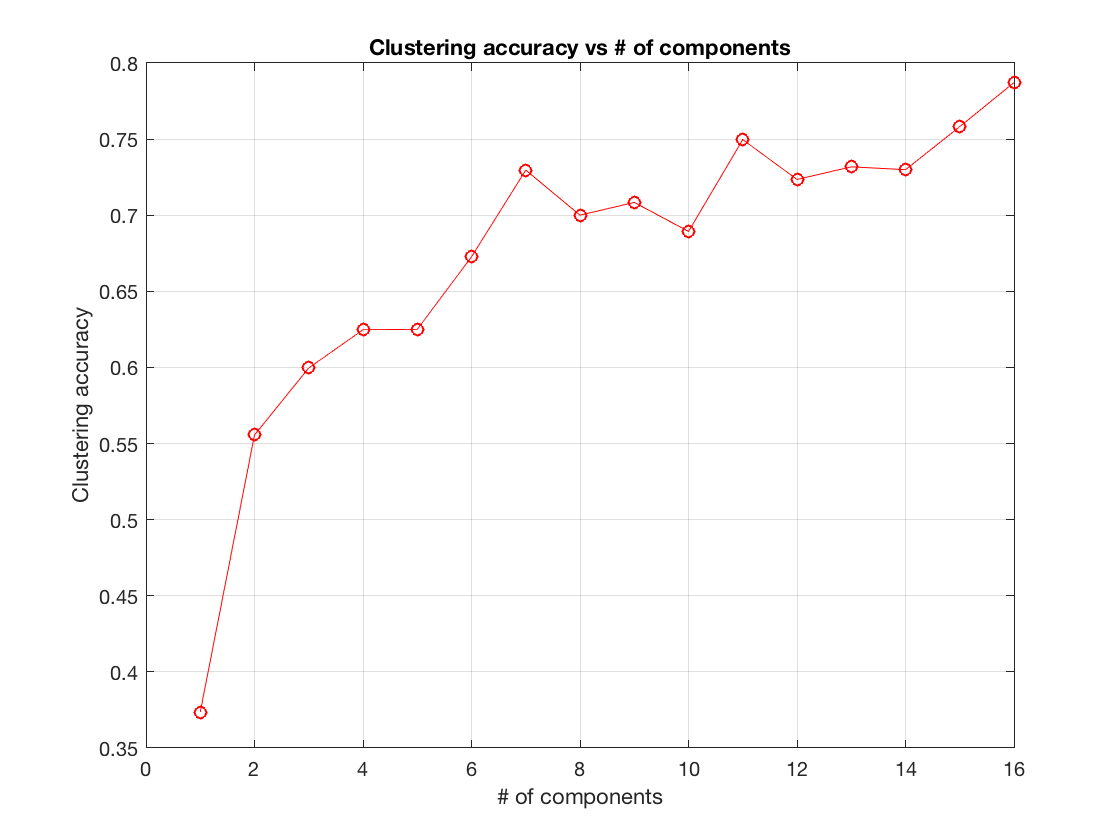

% saveas(gcf,'AccVsIter.png');

figure
plot(1:Dim,acc(:,end),'ro-');hold on;grid on;
title('Clustering accuracy vs # of components');
xlabel('# of components');ylabel('Clustering accuracy');

% saveas(gcf,'AccVsComp.png');